data = readmatrix('datos_grupo03_p04.xlsx')

data =          0   23.0000   23.2311   25.7651
    0.0141   23.0000   23.3842   25.7618
    0.0311   23.0000   23.3331   25.7583
    0.0461   23.0000   23.2821   25.7551
    0.0640   23.0000   23.2821   25.7520
    0.0789   23.0000   23.1801   25.7489
    0.0949   23.0000   23.3842   25.7459
    0.1060   23.0000   23.1801   25.7428
    0.1140   23.0000   23.1290   25.7385
    0.1282   23.0000   23.0270   25.7344


data2 = readmatrix('datos_grupo03_p04.xlsx','Range','A1:D1460')

data2 =          0   23.0000   23.2311   25.7651
    0.0141   23.0000   23.3842   25.7618
    0.0311   23.0000   23.3331   25.7583
    0.0461   23.0000   23.2821   25.7551
    0.0640   23.0000   23.2821   25.7520
    0.0789   23.0000   23.1801   25.7489
    0.0949   23.0000   23.3842   25.7459
    0.1060   23.0000   23.1801   25.7428
    0.1140   23.0000   23.1290   25.7385
    0.1282   23.0000   23.0270   25.7344


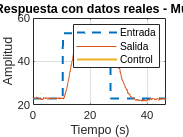



t = data(:,1);
u = data(:,2);
y = data(:,3);
c = data(:,4);



t2 = data2(:,1);
u2 = data2(:,2);
y2 = data2(:,3);
c2 = data2(:,4);

yn = y2 - mean(y2(1:10));
un = u2 - mean(u2(1:10));
cn = c2 - mean(c2(1:10));

figure(1)
plot(t, u,'--', LineWidth=1.5)
hold on
plot(t, y);
hold on;
plot(t, c, LineWidth=1.5);
title('Respuesta con datos reales - Murril')
legend('Entrada', 'Salida', 'Control')
xlabel('Tiempo (s)')
ylabel('Amplitud')
grid on
hold off

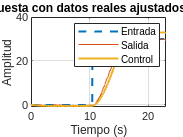



figure(2)
plot(t2, un,'--', LineWidth=1.5)
hold on
plot(t2, yn);
hold on;
plot(t2, cn, LineWidth=1.5);
title('Respuesta con datos reales ajustados - Murril')
legend('Entrada', 'Salida', 'Control')
xlabel('Tiempo (s)')
ylabel('Amplitud')
grid on
hold off

IAE = trapz(t2,abs(un-yn))

IAE = 98.7905

% Error permanente promedio
Eprem = mean(abs(cn-yn))

Eprem = 1.2536


% Sobrepaso máximo no normalizado
[Ymax1, indymax1] = max(yn,[],'all')

Ymax1 = 30.7592

indymax1 = 1312


% Valor final de la respuesta
Yf1 = mean(yn(1155:1460))

Yf1 = 30.0238


% Máximo de la señal realimentada 
Ymax = max(abs(max(yn)),abs(min(yn)))

Ymax = 30.7592


% Sobrepaso máximo normalizado
Mpnr = 100*(Ymax1-Ymax)/(Ymax)

Mpnr = 0


% Posición del vector de respuesta cuando llega a la banda del 2%
ind2per = find(yn>Ymax-0.02*(Ymax),1)-1

ind2per = 1134


% Tiempo de asentamiento al 2%
t2per1 = t2(ind2per)

t2per1 = 17.7075